% 1
clf

XR1CIED50 = 40.8483

YR1CIED50 = 49.8513

ZR1CIED50 = 20.2005

XR2CIED50 = 41.0368

YR2CIED50 = 49.8378

ZR2CIED50 = 20.3997

[XR1CIED65,YR1CIED65,ZR1CIED65] = spectra2xyz(R1, CIED65)

XR1CIED65 = 40.0489

YR1CIED65 = 49.7395

ZR1CIED65 = 26.6104

[XR2CIED65,YR2CIED65,ZR2CIED65] = spectra2xyz(R2, CIED65)

XR2CIED65 = 40.0489

YR2CIED65 = 49.7395

ZR2CIED65 = 26.6104


[XR1f11,YR1f11,ZR1f11] = spectra2xyz(R1, f11)

XR1f11 = 41.6587

YR1f11 = 53.3569

ZR1f11 = 16.3345

[XR2f11,YR2f11,ZR2f11] = spectra2xyz(R2, f11)

XR2f11 = 53.9818

YR2f11 = 63.4675

ZR2f11 = 20.7173

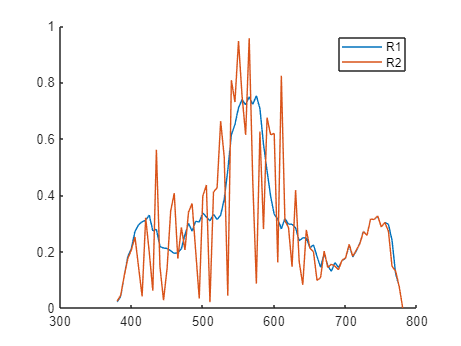


hold on;
plot(wavelength, R1);
plot(wavelength,R2);
legend("R1", "R2")
hold off;

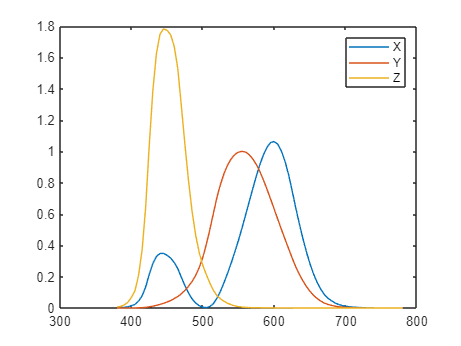


plot(wavelength,xyz);
legend("X", "Y", "Z")

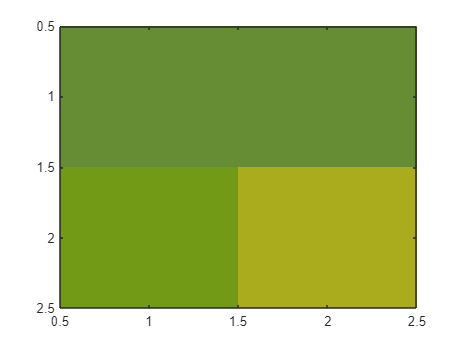


[R1CIED65r, R1CIED65b, R1CIED65g] = myxyz2rgb(XR1CIED65,YR1CIED65,ZR1CIED65);
[R2CIED65r, R2CIED65b, R3CIED65g] = myxyz2rgb(XR2CIED65,YR2CIED65,ZR2CIED65);

[R1f11r,R1f11b, R1f11g] = myxyz2rgb(XR1f11,YR1f11,ZR1f11);
[R2f11r,R3f11b, R4f11g] = myxyz2rgb(XR2f11,YR2f11,ZR2f11);

map = [[R1CIED65r, R1CIED65b, R1CIED65g] ;[R2CIED65r, R2CIED65b, R3CIED65g];
            [R1f11r,R1f11b, R1f11g];[R2f11r,R3f11b, R4f11g]];
map = min(1, max(0,map));
image([1 2;3 4]);
colormap(map)

% 2
clf
none = [80.43, 84.00, 96.50];
cyan = [25.84, 42.52, 80.88];
magenta = [37.36,18.44, 27.52];
cm = [7.40, 5.74, 40.36];
dotOffDot = 0.5 * cyan + 0.5 * magenta

dotOffDot =    31.6000   30.4800   54.2000


dotOnDot =    43.9150   44.8700   68.4300


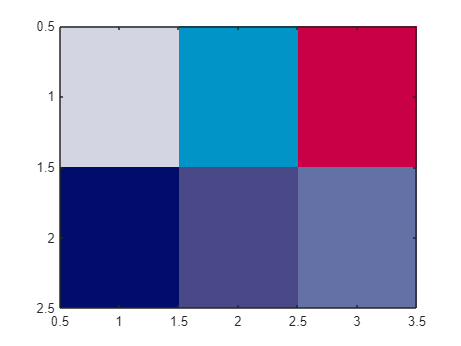


[noneR, noneG, noneB] = myxyz2rgb(none(:,1),none(:,2),none(:,3));
[cyanR, cyanG, cyanB] = myxyz2rgb(cyan(:,1),cyan(:,2),cyan(:,3));
[magentaR, magentaG, magentaB] = myxyz2rgb(magenta(:,1),magenta(:,2),magenta(:,3));
[cmR, cmG, cmB] = myxyz2rgb(cm(:,1),cm(:,2),cm(:,3));
[dotOffDotR, dotOffDotG, dotOffDotB] = myxyz2rgb(dotOffDot(:,1),dotOffDot(:,2),dotOffDot(:,3));
[dotOnDotR, dotOnDotG, dotOnDotB] = myxyz2rgb(dotOnDot(:,1),dotOnDot(:,2),dotOnDot(:,3));

map = [[noneR, noneG, noneB];[cyanR, cyanG, cyanB];[magentaR, magentaG, magentaB];w
    [cmR, cmG, cmB];[dotOffDotR, dotOffDotG, dotOffDotB];[dotOnDotR, dotOnDotG, dotOnDotB]];
map = min(1, max(0,map));
image([1 2 3; 4 5 6]);
colormap(map);

% 3
clf
[C, M,Y,K] = tiffread("halftone.tif");
Ctrans = C'

Ctrans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

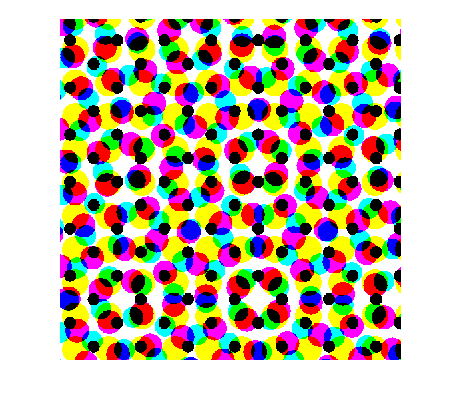

[R,G,B] = cmyk2rgb(C,M,Y,K);
[R1,G1,B1] = cmyk2rgb(Ctrans,M,Y,K);
imshowrgb(R,G,B)

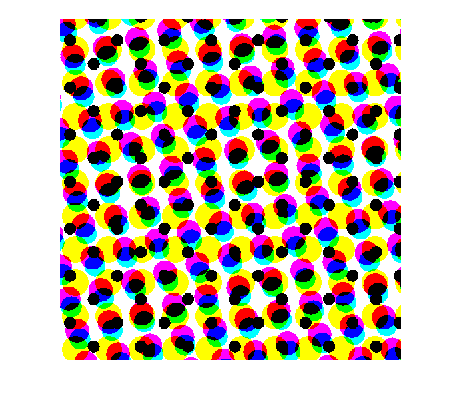

imshowrgb(R1,G1,B1)

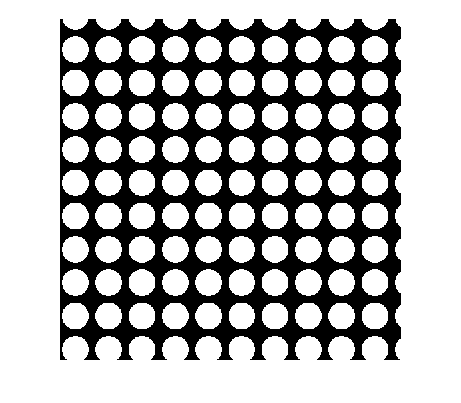

imshow(Y)

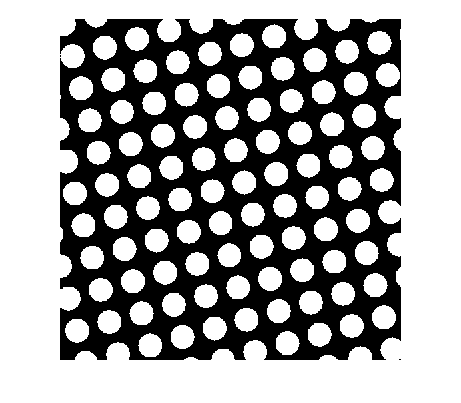

imshow(M)

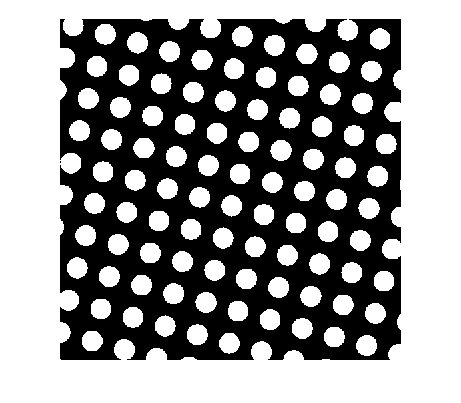

imshow(C)


C1 = C(129:384, 129:384);
C2 = C(139:394, 129:384);
M1 = M(129:384, 129:384);
M2 = M(139:394, 129:384);
Y1 = Y(129:384, 129:384);
Y2 = Y(139:394, 129:384);
K1 = K(129:384, 129:384);
K2 =K(139:394, 129:384);

Demichel_test(C1, M1, Y1, K1)

ans =     0.1628
    0.0765
    0.1351
    0.2090
    0.0191
    0.0648
    0.0858
    0.0096
    0.1126
    0.0185


Demichel_test(C2,M2,Y2,K2)

ans =     0.1662
    0.0753
    0.1327
    0.2031
    0.0183
    0.0584
    0.0895
    0.0101
    0.1172
    0.0198


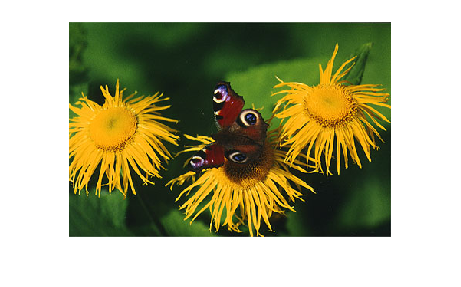

% 4
clf
[R, G, B] = tiffread('Butterfly.tif');
imshowrgb(R,G,B);

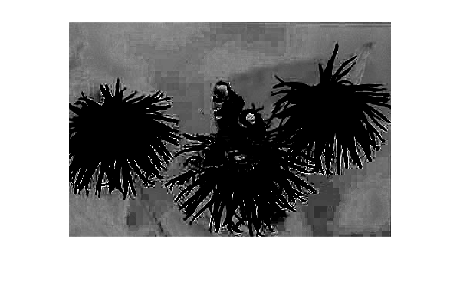


[C,M,Y,K] = rgb2cmyk(R,G,B);
figure(1)
imshow(C)

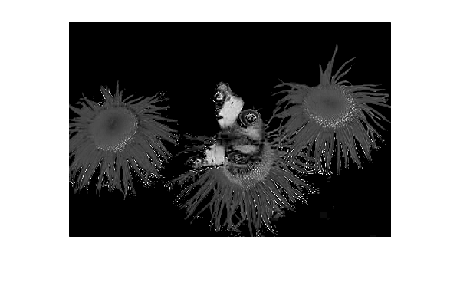

figure(2)
imshow(M)

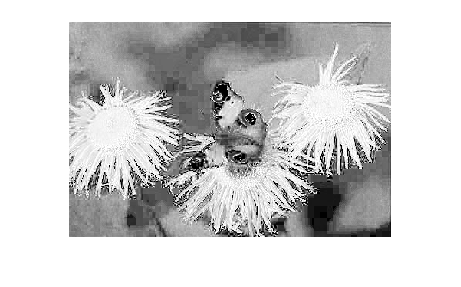

figure(3)
imshow(Y)

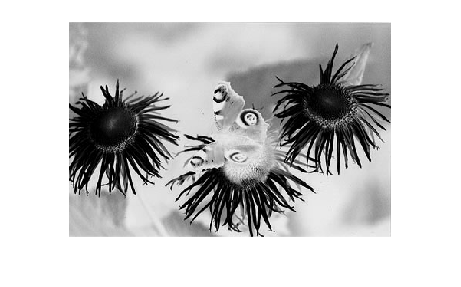

figure(4)
imshow(K)

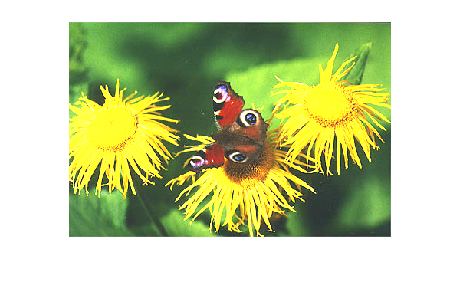


[L, a, b] = myrgb2lab(R,G,B);
[R2, G2, B2] = mylab2rgb(L+20, a,b);
imshowrgb(R2,G2,B2)

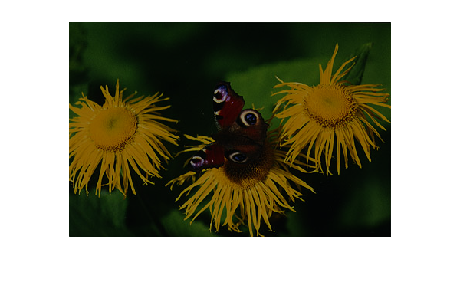

figure
[R3,G3,B3] = mylab2rgb(L-20,a,b);
imshowrgb(R3,G3,B3)

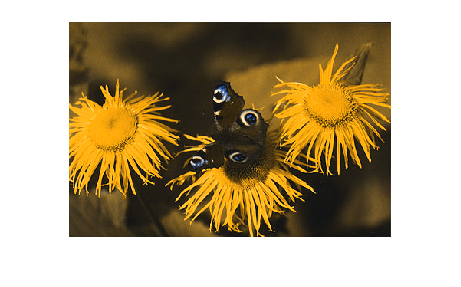


[R4,G4, B4] = mylab2rgb(L, a.*0, b);
imshowrgb(R4,G4,B4)

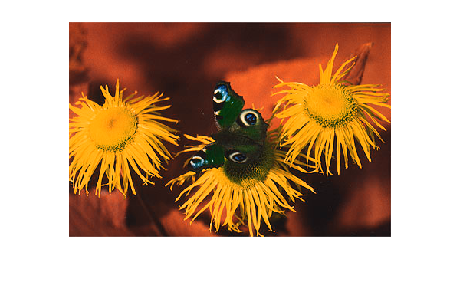


[R5,G5, B5] = mylab2rgb(L, a.*-1, b);
imshowrgb(R5,G5,B5)

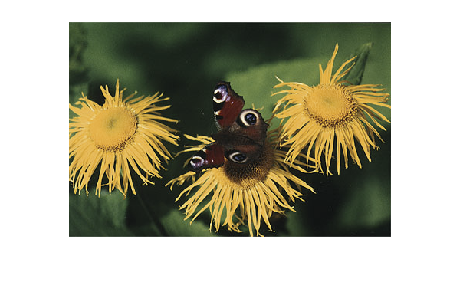


[R6,G6, B6] = mylab2rgb(L, 0.5*a, 0.5*b);
imshowrgb(R6,G6,B6)

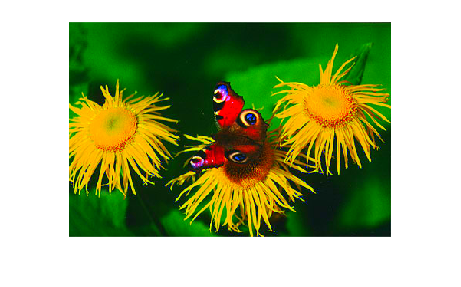


[R7,G7, B7] = mylab2rgb(L, 3*a, 3*b);
imshowrgb(R7,G7,B7)

% 5
[XC65,YC65,ZC65] = spectra2xyz(1,CIED65)

XC65 = 95.0437

YC65 = 100

ZC65 = 108.8818

[XT60,YT60,ZT60] = spectra2xyz(1,Tungsten60W)

XT60 = 112.9853

YT60 = 100.0000

ZT60 = 28.5810

[XP90,YP90,ZP90] = spectra2xyz(1,plank90K)

XP90 = 97.0578

YP90 = 100

ZP90 = 141.1759

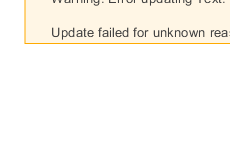


[RC65,GC65,BC65] = myxyz2rgb(XC65,YC65,ZC65);
[RT60,GT60,BT60] = myxyz2rgb(XT60,YT60,ZT60);
[RP90,GP90,BP90] = myxyz2rgb(XP90,YP90,ZP90);

showRGB([RC65,GC65,BC65]);

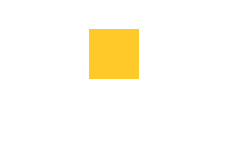

showRGB([RT60,GT60,BT60]);

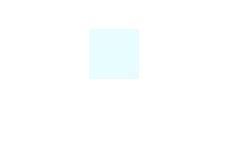

showRGB([RP90,GP90,BP90]);

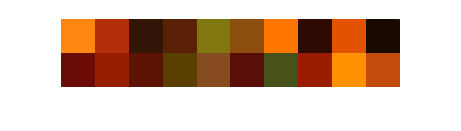

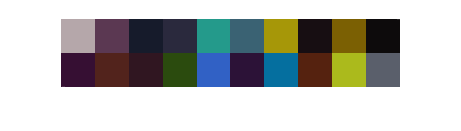

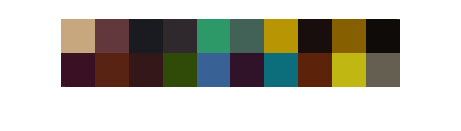


showRGB_20()

ans =    42.6575   37.7851    9.2111


ans =    35.5059   37.1884   45.1131


ans =    35.1115   37.2965   34.8667


ans =    67.8620   67.4182   67.4989


ans =     0.1015   -1.7637   -1.0122


ans =     7.4954    6.9190    7.0603


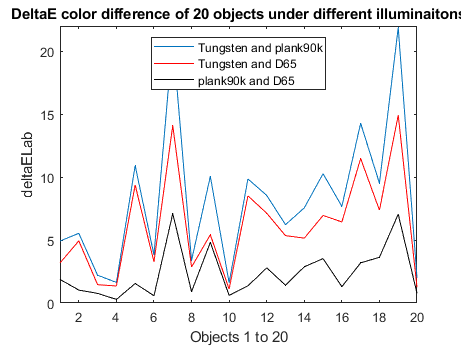

plot_deltaE();

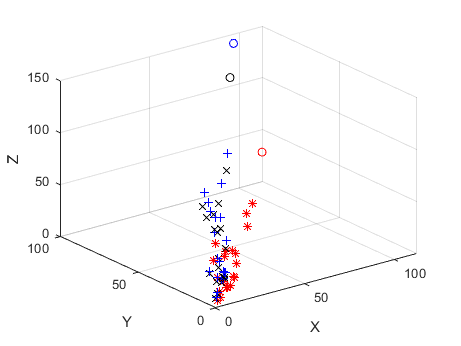

plot_XYZ();
grid on;

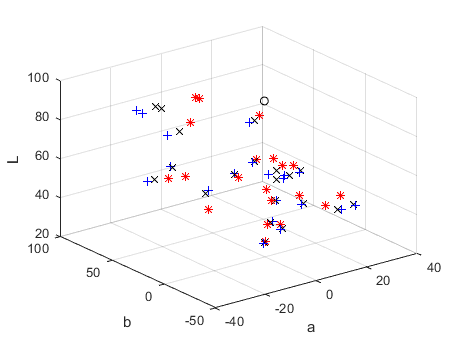


plot_Lab();
grid on;